% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;
pars.noise = 0;


% Define connectivity matrix for 5 neurons
conn_matrix = [0 1.5 0 0 0;
               0 0 1.5 1 0;
               0 0 0 0 1;
               -2 0 0 0 0;
               0 -2 0 0 0];

conn_matrix =          0    1.5000         0         0         0
         0         0    1.5000    1.0000         0
         0         0         0         0    1.0000
   -2.0000         0         0         0         0
         0   -2.0000         0         0         0


               
[nRow, nCol] =  size(conn_matrix);

nRow = 5

nCol = 5

if nRow ~= nCol
    fprintf('%s', 'Warning: Connectivity MAtrix is not Square \n')
end

%the number of neurons
num_neurons = length(conn_matrix);

% Initial conditions
l = length(conn_matrix);

x0 = zeros(l*5, 1); %l neurons, each with 5 state variables
for i = 1:5:length(conn_matrix)
    if i == 1
        x0(i) = -200e-3;
    else
        x0(i) = -68e-3;
    end
end
    
% Time span
tspan = [0 10];

% Solve the system
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), tspan, x0);

system_ss = x(end,:)*1.01;

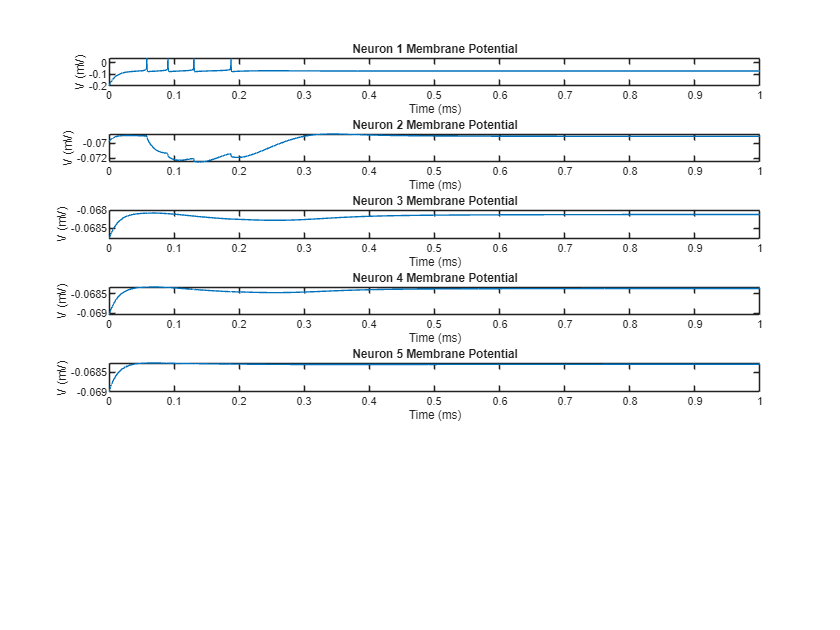

system_ss(1) = -200e-3;
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), [0 1], system_ss);

% Plot results
figure;
for i = 1:5
    subplot(7, 1, i);
    plot(t, x(:, (i-1)*5+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end

% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;
pars.noise = 0;


% Define connectivity matrix for 5 neurons
% first SWR attempt
conn_matrix = [0 1 0 0 0;
              0 0 1 1 0;
              0 0 0 0 1;
              -2 0 0 0 0;
              0 -2 0 0 0];

conn_matrix =      0     1     0     0     0
     0     0     1     1     0
     0     0     0     0     1
    -2     0     0     0     0
     0    -2     0     0     0



% feedforward reciprocal inhibition
%conn_matrix = [0 1 1 0;
%               1 0 0 1
%               0 -2 0 0;
%               -2 0 0 0]

% four neurons propagating forward
%conn_matrix = [ 0 1 0 0;
%                0 0 1 0;
%                0 0 0 1;
%                0 0 0 0]
[nRow, nCol] =  size(conn_matrix);

nRow = 5

nCol = 5

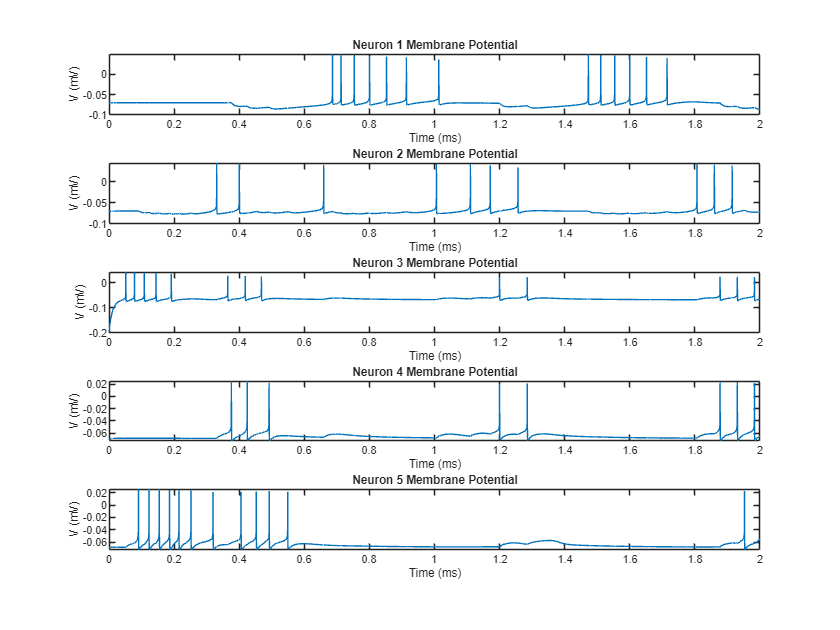

if nRow ~= nCol
    fprintf('%s', 'Warning: Connectivity MAtrix is not Square \n')
end

%the number of neurons
num_neurons = length(conn_matrix);

% Initial conditions
l = length(conn_matrix);

x0 = zeros(l*5, 1); %l neurons, each with 5 state variables
for i = 1:5:length(conn_matrix)
    if i == 1
        x0(i) = -200e-3;
    else
        x0(i) = -68e-3;
    end
end
    
% Time span
tspan = [0 20];

% Solve the system
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), tspan, x0);

system_ss = x(end,:)*1.01;
system_ss(11) = -200e-3;
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), [0 2], system_ss);

% Plot results
figure;
for i = 1:num_neurons
    subplot(5, 1, i);
    plot(t, x(:, (i-1)*5+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end

% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;
pars.noise = 0;


% Define connectivity matrix for 5 neurons
feedforward reciprocal inhibition
conn_matrix = [0 1 1 0;
               1 0 0 1
               0 -2 0 0;
               -2 0 0 0]

[nRow, nCol] =  size(conn_matrix);
if nRow ~= nCol
    fprintf('%s', 'Warning: Connectivity MAtrix is not Square \n')
end

%the number of neurons
num_neurons = length(conn_matrix);

% Initial conditions
l = length(conn_matrix);

x0 = zeros(l*5, 1); %l neurons, each with 5 state variables
for i = 1:5:length(conn_matrix)
    if i == 1
        x0(i) = -200e-3;
    else
        x0(i) = -68e-3;
    end
end
    
% Time span
tspan = [0 20];

% Solve the system
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), tspan, x0);

system_ss = x(end,:)*1.01;
system_ss(11) = -200e-3;
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), [0 2], system_ss);

% Plot results
figure;
for i = 1:num_neurons
    subplot(5, 1, i);
    plot(t, x(:, (i-1)*5+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end

% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;
pars.noise = 0;


% Define connectivity matrix for 5 neurons

 four neurons propagating forward
conn_matrix = [ 0 1 0 0;
                0 0 1 0;
                0 0 0 1;
                0 0 0 0]
[nRow, nCol] =  size(conn_matrix);
if nRow ~= nCol
    fprintf('%s', 'Warning: Connectivity MAtrix is not Square \n')
end

%the number of neurons
num_neurons = length(conn_matrix);

% Initial conditions
l = length(conn_matrix);

x0 = zeros(l*5, 1); %l neurons, each with 5 state variables
for i = 1:5:length(conn_matrix)
    if i == 1
        x0(i) = -200e-3;
    else
        x0(i) = -68e-3;
    end
end
    
% Time span
tspan = [0 20];

% Solve the system
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), tspan, x0);

system_ss = x(end,:)*1.01;
system_ss(11) = -200e-3;
[t, x] = ode45(@(t, x) generate_neuron_model(t, x, pars, conn_matrix), [0 2], system_ss);

% Plot results
figure;
for i = 1:num_neurons
    subplot(5, 1, i);
    plot(t, x(:, (i-1)*5+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end

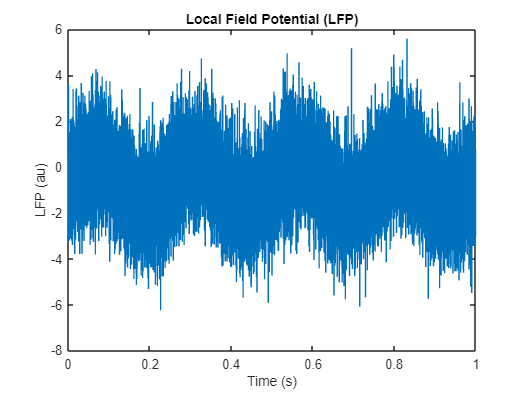

% Assuming the targeted neurons's outputs are your CA1 neuron outputs
% Each of these variables should be a column vector [voltage] and they all
% share the same time vector because they were computed using the same
% ODE45 function
neuron_outputs = {};
targeted_neuron_index = [1,3,5];
for i = targeted_neuron_index
    neuron_outputs{end+1} = x(:, (i-1)*5+1);
end

% Call the LFP measurement model
LFP = lfpMeasurementRetrofitted(t, 1000, neuron_outputs);

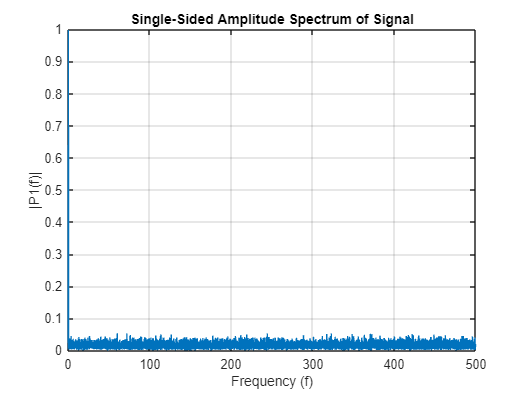

% Generate a sample signal
Fs = 1000;                   % Sampling frequency (Hz)
t = 0:1/Fs:1-1/Fs;           % Time vector (1 second)


% Compute FFT
n = length(LFP);          % Number of samples
f_transform = fft(LFP);   % Compute the FFT

% Compute the two-sided spectrum P2
P2 = abs(f_transform/n);

% Compute the single-sided spectrum P1
P1 = P2(1:n/2+1);
P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain f
f = Fs*(0:(n/2))/n;

% Plot the single-sided amplitude spectrum
figure;
plot(f, P1)
title('Single-Sided Amplitude Spectrum of Signal')
xlabel('Frequency (f)')
ylabel('|P1(f)|')
grid on;

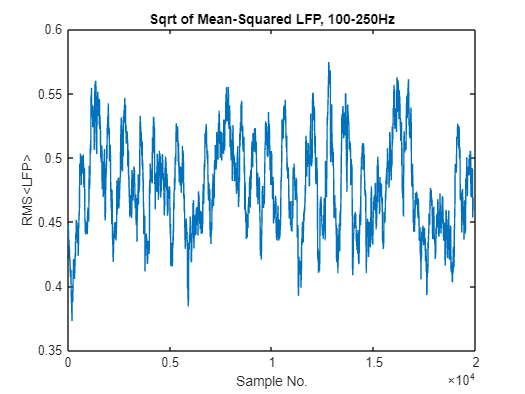

% Design a simple high-pass filter (cutoff at 100 Hz)
hp_cutoff = 100;
hp_filtered = LFP - movmean(LFP, round(1000 / hp_cutoff));

% Design a simple low-pass filter (cutoff at 250 Hz)
lp_cutoff = 250;
lp_filtered = movmean(hp_filtered, round(1000 / lp_cutoff));

csc_rms = sqrt(movmean(lp_filtered.^2, 250));
figure;
plot(csc_rms)
xlabel('Sample No.')
ylabel('RMS<LFP>')
title('Sqrt of Mean-Squared LFP, 100-250Hz')

% Define parameters (example)
pars.gleak = 10e-9;
pars.gnamax = 3.6e-6;
pars.gkmax = 1.6e-6;
pars.gtmax = 0.22e-6;
pars.ena = 55e-3;
pars.ek = -90e-3;
pars.eca = 120e-3;
pars.el = -70e-3;
pars.cm = 100e-12;
pars.baseCurrentFrq = 0;

pars.syn_a = 1000;
pars.syn_b = 5;
pars.gsynmax = 0.08e-8;
pars.esyn = 100e-3;
pars.noise = 1;

% Define connectivity matrix for 5 neurons
conn_matrix = [0 1 1 0;
               1 0 0 1;
               0 -1.4 0 0;
               -1.4 0 0 0];

conn_matrix =          0    1.0000    1.0000         0
    1.0000         0         0    1.0000
         0   -1.4000         0         0
   -1.4000         0         0         0


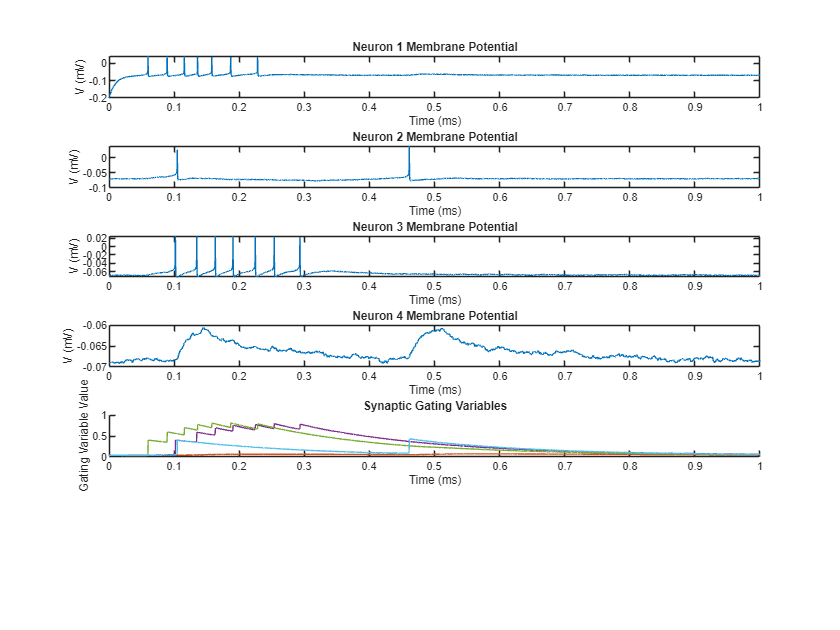


[nRow, nCol] = size(conn_matrix);
if nRow ~= nCol
    fprintf('%s', 'Warning: Connectivity Matrix is not Square \n');
end

% Number of neurons
num_neurons = length(conn_matrix);

% Initial conditions
num_synapses = nnz(conn_matrix); % Number of non-zero elements in conn_matrix
x0 = zeros(num_neurons * 4 + num_synapses, 1); % 4 state variables per neuron + synaptic gating variables

% Initialize membrane potentials
for i = 1:num_neurons
    V_idx = (i - 1) * 4 + 1;
    if i == 1
        x0(V_idx) = -200e-3;
    else
        x0(V_idx) = -68e-3;
    end
end

% Initialize synaptic gating variables (all to zero)
% This is done by default with the zeros function

% Time span
tspan = [0 10];

% Solve the system
[t, x] = ode45(@(t, x) new_neuron_model(t, x, pars, conn_matrix), tspan, x0);

% Steady state perturbation
system_ss = x(end, :) * 1.01;
system_ss(1) = -200e-3;

[t, x] = ode45(@(t, x) new_neuron_model(t, x, pars, conn_matrix), [0 1], system_ss);

% Plot results
figure;
for i = 1:num_neurons
    subplot(num_neurons + 2, 1, i);
    plot(t, x(:, (i-1)*4+1));
    title(['Neuron ' num2str(i) ' Membrane Potential']);
    xlabel('Time (ms)');
    ylabel('V (mV)');
end

% Plot synaptic gating variables
synapse_counter = num_neurons * 4;
for i = 1:num_neurons
    for j = 1:num_neurons
        if conn_matrix(i, j) ~= 0
            synapse_counter = synapse_counter + 1;
            subplot(num_neurons + 2, 1, num_neurons + 1);
            hold on;
            plot(t, x(:, synapse_counter));
        end
    end
end
title('Synaptic Gating Variables');
xlabel('Time (ms)');
ylabel('Gating Variable Value');
hold off;